# Illustrative Test

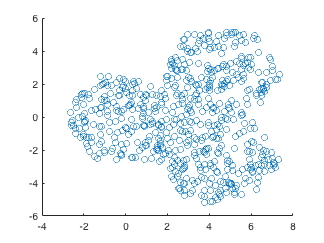

r = 3;
k = 200;
l = 3;

network = Network(r, k, l);
points = network.getUsers();
scatter(points(:, 1), points(:, 2))

## Realistic Test

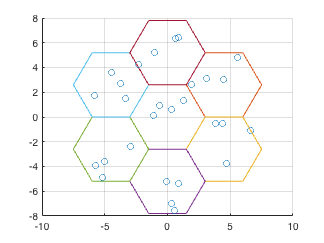

r = 3;
k = 4;
l = 7;

network = Network(r, k, l);
points = network.getUsers();
figure
network.tracePerimeters(true);
hold on
scatter(points(:, 1), points(:, 2))
hold off
grid on

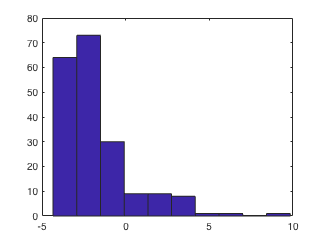



lsfcs = network.calculateLSFCs();
hist(log(lsfcs(:)))

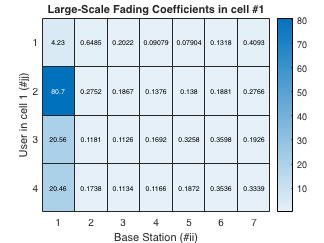

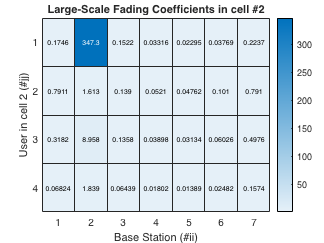

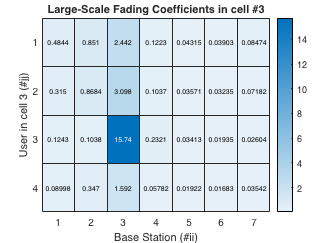

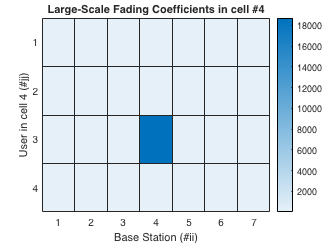

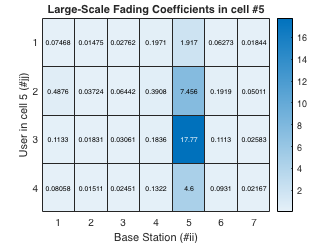

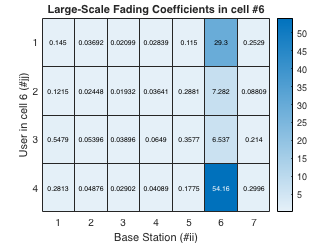

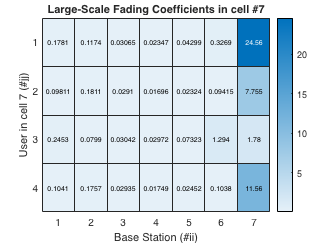

for ii = 1:l
    figure
    heatmap(squeeze(lsfcs(:, ii, :)))
    xlabel("Base Station (#ii)")
    ylabel("User in cell " + ii + " (#jj)")
    title("Large-Scale Fading Coefficients in cell #" + ii)
end

## PCS

zetas = network.pilotContaminationSeverities(true);
zetas2 = network.pilotContaminationSeverities(false);
figure
heatmap(log(zetas))
xlabel("jj + kk for user jj in cell kk")
ylabel("jj' + kk' for user jj' in cell kk'")
title("ln[Pilot Containation Severity]")

Spot Check

jj = 3;
kk = 5;
jj2 = 4;
kk2 = 7;
zetas2(jj, kk, jj2, kk2)
network.pilotContaminationSeverity(jj, kk, jj2, kk2)